% TODO:
% 1. have way of passing generate_H cell, and then just load all of those
%    patterns simulateously in 1 go instead of as separate runs
%
% ---- PATH -----
% Matlab uses startup.m to run startup code...
% Put this in your startup.m so that the code for this is in path:
%
% addpath(genpath('/Volumes/MATLAB-Drive/')) % or wherever your CODE files are
% located
% addpath(genpath('~/Data/Raw/')) % or wherever your DATA files are located

% ===================================================
% OPTION STRUCT encoding properties of the script run
% ===================================================
% see +option.default() to set default options
if ~exist('Option','var')
    Option = option.defaults();
else
    Option = option.setdefaults(Option);
end

Default = 包含以下字段的 struct :
                           animal: "ZT2"
                     samplingRate: []
                     spikeBinSize: 0.0500
                          winSize: [0 0.3000]
          positiveDerivativeCheck: [0 0.1500]
       equalWindowsAcrossPatterns: 1
            quantileToMakeWindows: 0.8500
       thetadelta_outlierQuantile: [0 0.9950]
                   spikeShiftSize: 0.0100
                    timesPerTrial: 30
                       sourceArea: "CA1"
                 waysOfPartitions: 2
                    singleControl: 0
               oldControlBehavior: 0
                     lowerControl: 1
                    binsToMatchFR: 20
           preProcess_FilterLowFR: 1
    preProcess_matchingDiscreteFR: 1
        preProcess_gaussianFilter: 5
                preProcess_zscore: 1
                     numPartition: 50
                  dimCompAnalysis: 5
                       stablePerf: 0.9000
                        generateH: "fromSpectra  fromRipTimes"



Option.numPartition = 2;
Option.positiveDerivativeCheck = [0 0.01];
Option.generateH = "fromFilteredEEG  fromRipTimes";

%%%%%%%%%%%%%%%% DISPLAY OUR OPTIONS TO USER %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp("Running with Option struct => ")

Running with Option struct => 


disp(Option);

                           animal: "ZT2"
                     samplingRate: []
                     spikeBinSize: 0.0500
                          winSize: [0 0.3000]
          positiveDerivativeCheck: [0 0.0100]
       equalWindowsAcrossPatterns: 1
            quantileToMakeWindows: 0.8500
                       maxWindows: ["ripple"    "1200"]
       thetadelta_outlierQuantile: [0 0.9950]
                   spikeShiftSize: 0.0100
                    timesPerTrial: 30
                       sourceArea: "CA1"
                 waysOfPartitions: 2
                    singleControl: 0
               oldControlBehavior: 0
                     lowerControl: 1
                    binsToMatchFR: 20
           preProcess_FilterLowFR: 1
    preProcess_matchingDiscreteFR: 1
        preProcess_gaussianFilter: 5
                preProcess_zscore: 1
                     numPartition: 2
                  dimCompAnalysis: 5
                       stablePerf: 0.9000
                        generateH: 


%%%%%%%%%%%%%%%% OBTAIN EVENT MATRICES    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp("------------------------")

------------------------


disp("    Obtaining events    ")

    Obtaining events    


disp("------------------------")

------------------------


Events = events.ThetaDeltaRipple(Option);

Generating event matrix for fromFilteredEEGfromRipTimes
Set all globalripple times to globalripple amp
Event matrix generated 123.6995 seconds


% Documentation
% Events is a struct with fields:
% - .times : array of times of events
% - .H     : Event Matrix,    T x 3, and each column are theta, delta, ripple
% - .Hvals : Event Matrix,    T x 3, values without nans
% - .Hnanlocs : Event Matrix, T x 3, logicals of nans


%%%%%%%%%%%%%%%% CUT WINDOWS WITH EVENT MATRICES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp("------------------------")

------------------------


disp("    Cutting windows     ")

    Cutting windows     


disp("------------------------")

------------------------


Events = windows.ThetaDeltaRipple(Events, Option);

Generating windows for events
Derivative mode for Pattern 1
...fraction of positive derivative windows: 0.072458
Derivative mode for Pattern 2
...fraction of positive derivative windows: 0.16805


--------------------------
initial window creation
--------------------------
1795 windows for theta
1318 windows for delta
1858 windows for ripple
2.671098e+04 timerange for theta
2.671088e+04 timerange for delta
2.671356e+04 timerange for ripple


--------------------------
equalize windows
--------------------------
1236 windows for theta
1318 windows for delta
1169 windows for ripple
2.617943e+04 timerange for theta
2.671088e+04 timerange for delta
2.615447e+04 timerange for ripple
Derivative mode for Pattern 1
...fraction of positive derivative windows: 0.11567
Derivative mode for Pattern 2
...fraction of positive derivative windows: 0.20975
Windows generated 1236 windows cut
  time elapsed: 15.1753 seconds
  cutoffs: 175            68             1      62.33333      20.66667      6.666

% -  cutoffs:       nPatterns x 1 vector of cutoffs
% TODO: modify to be able to include overall pattern and track patterns
% PRIORITY; overall: medium, track: very low, overall can be included in
% cellOfWindows, whereas, track can be included as a separate output



## ACQUIRE SPIKES 

Getting spikes

disp("------------------------")

------------------------


disp("    Getting spikes      ")

    Getting spikes      


disp("------------------------")

------------------------


Spk = spikes.getSpikeTrain(Option.animal, Option.spikeBinSize, ...
    Option.samplingRate);

...loading spikes for ZT2
...finding start and end times of the day
...done 22.2867 seconds



% filter the neurons whose firing rate is lower than specified threshold
if Option.preProcess_FilterLowFR
    disp("------------------------")
    disp("Filtering low FR neurons")
    disp("------------------------")
    Spk = trialSpikes.filterFR(Spk, 0.1);
    disp("Mean FR: " + sort(Spk.avgFR))
end

------------------------


Filtering low FR neurons


------------------------


    "Mean FR: 0.111289"
    "Mean FR: 0.114746"
    "Mean FR: 0.116194"
    "Mean FR: 0.116951"
    "Mean FR: 0.120111"
    "Mean FR: 0.120473"
    "Mean FR: 0.120703"
    "Mean FR: 0.120967"
    "Mean FR: 0.124357"
    "Mean FR: 0.127023"
    "Mean FR: 0.131763"
    "Mean FR: 0.132125"
    "Mean FR: 0.133277"
    "Mean FR: 0.135318"
    "Mean FR: 0.136832"
    "Mean FR: 0.14019"
    "Mean FR: 0.141473"
    "Mean FR: 0.147596"
    "Mean FR: 0.156845"
    "Mean FR: 0.157833"
    "Mean FR: 0.170078"
    "Mean FR: 0.17281"
    "Mean FR: 0.175904"
    "Mean FR: 0.188544"
    "Mean FR: 0.192296"
    "Mean FR: 0.196147"
    "Mean FR: 0.197233"
    "Mean FR: 0.200525"
    "Mean FR: 0.203619"
    "Mean FR: 0.205331"
    "Mean FR: 0.208359"
    "Mean FR: 0.211157"
    "Mean FR: 0.211486"
    "Mean FR: 0.213955"
    "Mean FR: 0.214054"
    "Mean FR: 0.214152"
    "Mean FR: 0.218761"
    "Mean FR: 0.228372"
    "Mean FR: 0.228701"
    "Mean FR: 0.238905"
    "Mean FR: 0.239596"
    "Mean FR: 0.25


if Option.preProcess_gaussianFilter
    % Gaussian filter the spikeCountMatrix/spikeRateMatrix
    gauss = gausswin(Option.preProcess_gaussianFilter);
    for i = progress(1:size(Spk.spikeRateMatrix, 1), 'Title', 'Gaussian filtering')
        Spk.spikeRateMatrix(i, :)  = conv(Spk.spikeRateMatrix(i, :), gauss, 'same');
        Spk.spikeCountMatrix(i, :) = conv(Spk.spikeCountMatrix(i, :), gauss, 'same');
    end
end

Gaussian filtering:  000%  |                                        | 0/224 [00:00:00<Inf:NaN:NaN, Inf it/s]


if Option.preProcess_zscore
    % Z-score the spikeCountMatrix/spikeRateMatrix
    disp(" Z-scoring ")
    Spk.spikeRateMatrix  = zscore(Spk.spikeRateMatrix,  0, 2);
    Spk.spikeCountMatrix = zscore(Spk.spikeCountMatrix, 0, 2);
    Spk.avgFR = mean(Spk.spikeRateMatrix, 2);
end

 Z-scoring 


prewindow_copy = Spk;


%%%%%%%%%%%%%%%% ACQUIRE TRIALS FROM WINDOWS + SPIKES %%%%%%%%%%%%%%%%%%%
% RYAN bug here .. timeBinStartEnd instead of timeBinMidPoints
disp("------------------------")

------------------------


disp("   Windowing spikes     ")

   Windowing spikes     


disp("------------------------")

------------------------


Spk = trialSpikes.generate(Spk, Events, Option);

Generating spike sample matrix and tensor
Patterns:  000%  |                                            | 0/6 [00:00:00<Inf:NaN:NaN, Inf it/s


## SETUP RAW DATA STRUCTURE 

Structure for separated data

%%%%%%%%%%%%%%%% SEPRATE BRAIN AREA DATASULT STRUCTURES %%%%%%%%%%%%%%%%%%
% Separate spikesSampleMatrix/Tensor by area that neurons are in PFC and
% neurons that in HPC

Separate firing pattern into source and target

[Spk.nSource,~,~] = size(Spk.hpc.T{1});
[Spk.nTarget,~,~] = size(Spk.pfc.T{1});
Spk.celllookup = cellInfo.getCellIdentities(Option.animal, Spk.cell_index,...
    Spk.areaPerNeuron);

%%%%%%%%%%%%%%%% SETUP PARTITIONS AND RESULT STRUCTURES %%%%%%%%%%%%%%%%%%
disp("------------------------")
disp(" Subsampling partitions ")
disp("------------------------")
% if to get data [neurons, timepoints], use trialSpikes.partitionAndInitialize
% if to get data [neurons, times, trials], use trialSpikes.partitionAndInitialize_3D
[Patterns, Patterns_overall] = trialSpikes.partitionAndInitialize_3D(Spk, Option);

## Analysis

%%%%%%%%%%%%%%%% ANALYSIS SECTION    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
disp("------------------------")
disp("     Analysis           ")
disp("------------------------")

if Option.analysis.rankRegress
    % Rank regression of network pattern windows of spiking activity
    % (Subspaces acquired here)
    % TODO:
    % 1. fix Option.rankregress => Option.rankRegress
    % 2. most rankRegress.B_ are empty
    Patterns         = analysis.rankRegress(Patterns, Option);
    Patterns_overall = analysis.rankRegress(Patterns_overall, Option);
end

if Option.analysis.factorAnalysis
    % Factor analysis of network pattern windows of spiking activity
    % (Used to measure instrinsic dimensionality of network activity)
    Patterns = analysis.factorAnalysis(Patterns, Option);
end

if Option.analysis.cca
    % ISSUE: warnings emitted regarding full rank -- linear independence
    % violation can be subtle problem or not a problem at all
    % remedies (1) regularize (2) remove linearly dependent columns (PCA)
    Patterns         = analysis.cca(Patterns, Option);
    Patterns_overall = analysis.cca(Patterns_overall, Option);
    % TODO : section that knocks off kim 2022 after these measurements
end

if Option.analysis.timeVarying
    % How much spiking moment to moment is explained by subspace
    % ISSUE: hits a bug on line 4
    % TODO: 1 .also return epochwise zscored neural firing matching
    %       2. return timeseries of smoothed firing rate
    running_times = Spk.timeBinMidPoints(Spk.sessionTypePerBin == 1);
    [behavior, thrown_out_times] = table.behavior.lookup(Option.animal, ...
        running_times);
    Components = analysis.timeVarying_v2(Patterns, Option, Spk);
    Components = plots.temporal.correlateSpectral(Components, Events, Option);
    Components = plots.temporal.correlateBehavior(Components, Events, Option);
end

if Option.analysis.checks
    % Plots regarding the raw and processed data (and sometimes
    % relation to processed Patterns struct)
    % TODO: Think about splitting this into checks involving
    %        versus not involving the Patterns struct
    if strcmp(Option.animal, "JS21"); wait_state = true;
    else; wait_state = false; end;
    plots.runChecks(Events, Spk, Patterns, Option, ...
        'parallel', true, 'wait', wait_state);
end

% TODO: (1) plug in JPECC version of rankRegress here
% TODO: (2) function that outputs average response of Pattern struct per neuron

## JPECC

warning("off","all")
disp("------------------------")
disp("        jpecc           ")
disp("------------------------")

Option.analysis.JPECC = 1;

%if Rank Reduced Regression, use "JPECC_RRR"
%if CCA, use "JPECC"
if Option.analysis.JPECC
    %J_Patterns         = analysis.JPECC(Patterns, Option);
    J_Patterns2 = analysis.JPECC(Patterns, Option);
    %J_Patterns3 = analysis.JPECC(Patterns, Option);
    %J_Patterns4 = analysis.JPECC(Patterns, Option);
end

------------------------


        jpecc           


------------------------


----------
     1

----------


Spk.hpc.T

ans = 1×3 cell 数组
    {132×30×385 double}    {132×30×385 double}    {132×30×2000 double}


Gaussian

sigma = 0.7;
filter_size = 2;
[x, y] = meshgrid(-filter_size:filter_size, -filter_size:filter_size);
h = exp(-(x.^2 + y.^2) / (2 * sigma^2));
h = h / sum(h(:));  % normalize the filter


meanMatrix

meanMatrix =     0.6839    0.1141    0.0736    0.0417    0.0414    0.0218    0.0481    0.0850    0.0558    0.1073    0.1952    0.0989    0.1141    0.1817    0.1027    0.0843    0.0569    0.0628    0.1492    0.1489    0.0823    0.1051    0.1605    0.1639    0.1461    0.1323    0.0754    0.0461    0.0641   -0.0822
    0.0835    0.3249    0.3194    0.3727    0.4475    0.3514    0.2147    0.4622    0.1127    0.2513    0.2486    0.3396    0.4204    0.4603    0.3147    0.3409    0.3222    0.3358    0.3209    0.2654    0.2521    0.1757    0.3032    0.2012    0.3005    0.4437    0.3179    0.2496    0.2932    0.1368
    0.0896    0.3468    0.2211    0.2928    0.2911    0.4097    0.4167    0.4548    0.0688    0.1456    0.1593    0.1962    0.2871    0.2967    0.4117    0.3392    0.3219    0.3001    0.2443    0.3898    0.4372    0.3988    0.3522    0.2239    0.2503    0.3516    0.2471    0.2757    0.3140    0.1260
    0.1093    0.4701    0.3627    0.2582    0.1726    0.4036    0.4385    0.4970    


stackedMatrices = cell(1, 40);
for i = 1:40
    x = nd.fieldGet(J_Patterns(i).jpecc, "val1");
    stackedMatrices{1,i} = x;
end
stackedMatrice = cat(40, stackedMatrices{1,:});
meanMatrix = nanmean(stackedMatrice, 40);
%{
stackedMatrices2 = cell(1, 40);
for i = 1:40
    x = nd.fieldGet(J_Patterns2(i).jpecc, "val1");
    stackedMatrices2{1,i} = x;
end
stackedMatrice2 = cat(40, stackedMatrices2{1,:});
meanMatrix2 = nanmean(stackedMatrice2, 40);

stackedMatrices3 = cell(1, 40);
for i = 1:40
    x = nd.fieldGet(J_Patterns3(i).jpecc, "val1");
    stackedMatrices3{1,i} = x;
end
stackedMatrice3 = cat(40, stackedMatrices3{1,:});
meanMatrix3 = nanmean(stackedMatrice3, 40);

stackedMatrices4 = cell(1, 40);
for i = 1:40
    x = nd.fieldGet(J_Patterns4(i).jpecc, "val1");
    stackedMatrices4{1,i} = x;
end
stackedMatrice4 = cat(40, stackedMatrices4{1,:});
meanMatrix4 = nanmean(stackedMatrice4, 40);
%}

% 创建一个颜色矩阵
n = 256; % 颜色的数量

% 定义橙黄色和天蓝色
orange_yellow = [1, 0.7, 0];
sky_blue = [0.5, 0.75, 1];

% 创建颜色矩阵
r = [linspace(orange_yellow(1), 1, n/4)'; linspace(1, 0, 6*n/8)'; linspace(0, 0.4, 6*n/8)'; linspace(0.4, sky_blue(1), n/4)'];
g = [linspace(orange_yellow(2), 0.13, n/4)'; linspace(0, 0, 6*n/8)'; linspace(0, 0.5, 6*n/8)'; linspace(0.5, sky_blue(2), n/4)'];
b = [linspace(orange_yellow(3), 0, n/4)'; linspace(0, 0, 6*n/8)'; linspace(0, 1, 6*n/8)'; linspace(1, sky_blue(3), n/4)'];

cmap = [r, g, b];
cmap = flipud(cmap.^1.1)

cmap =     0.4665    0.7287    1.0000
    0.4649    0.7245    1.0000
    0.4633    0.7203    1.0000
    0.4616    0.7160    1.0000
    0.4600    0.7118    1.0000
    0.4584    0.7076    1.0000
    0.4568    0.7033    1.0000
    0.4551    0.6991    1.0000
    0.4535    0.6949    1.0000
    0.4519    0.6907    1.0000


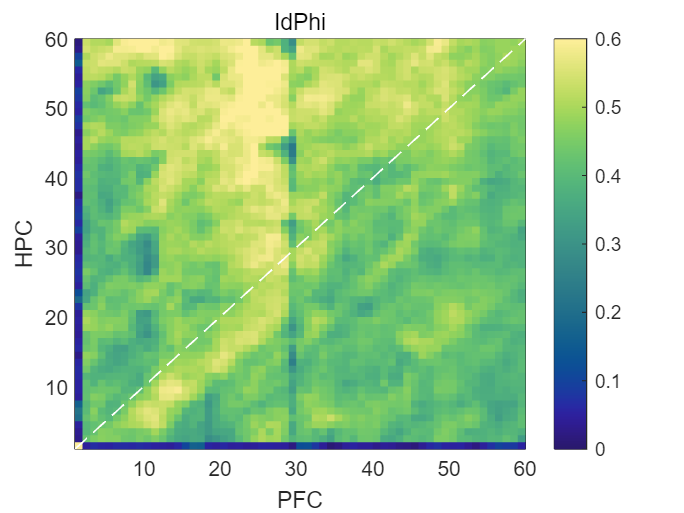

lindist_trajbound = meanMatrix;
%lindist_trajbound = conv2(lindist_trajbound, h, 'same');

% heatmap
figure;
t = pcolor(lindist_trajbound);
%shading interp;

caxis([0 0.6]);
cmocean('haline')
colorbar

%{
%caxis([-0.4 0.4]);
colormap(cmap);
colorbar;
%}

set(t, 'EdgeColor', 'none');
line([1 60], [1 60], 'Color', [1,1,1], 'LineWidth', 0.8,"LineStyle", "--");

xlabel('PFC');
ylabel('HPC');
title('IdPhi');
saveas(gcf, "F:\ComSub\Figures\idphi and reward\Idphi.png");

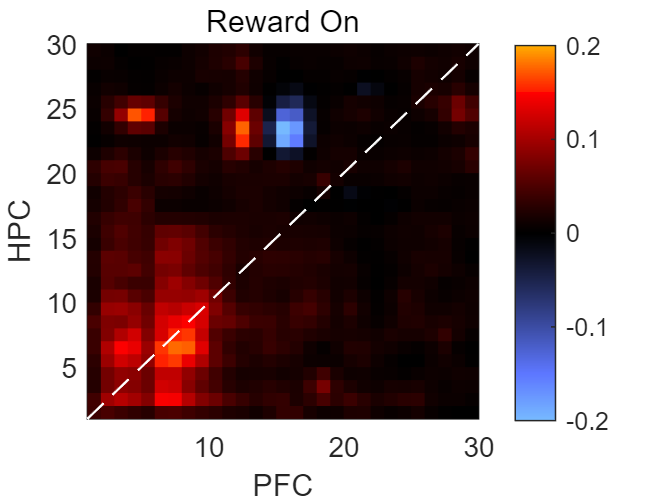

lindist_trajbound = meanMatrix2;
lindist_trajbound = conv2(lindist_trajbound, h, 'same');

% heatmap
figure;
t = pcolor(lindist_trajbound);
%shading interp;

%{
caxis([-0.3 0.4]*0.8);
cmocean('tarn','pivot',0,'negative')
colorbar
%}

caxis([-0.2 0.2]);
colormap(cmap);
colorbar;


set(t, 'EdgeColor', 'none');
line([1 30], [1 30], 'Color', [1,1,1], 'LineWidth', 0.8,"LineStyle", "--");

xlabel('PFC');
ylabel('HPC');
title('Reward On');

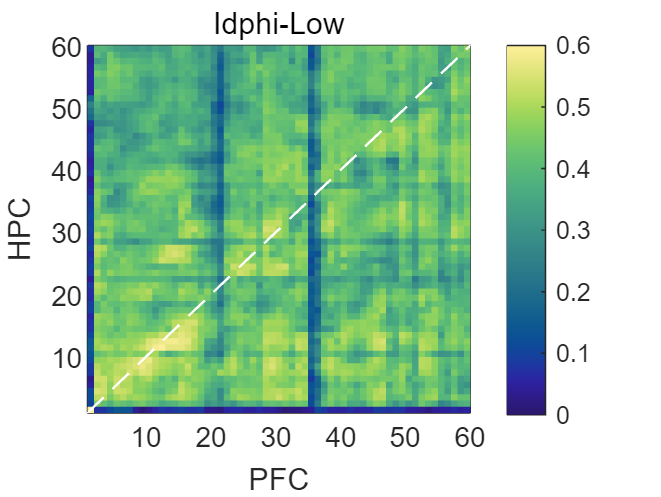

lindist_trajbound2 = meanMatrix2;
%lindist_trajbound2 = conv2(lindist_trajbound2, h, 'same');

% heatmap
figure;
t = pcolor(lindist_trajbound2);
%shading interp;


caxis([0 0.6]);
cmocean('haline')
colorbar

%{
%caxis([-0.7 0.7]);
colormap(cmap);
colorbar;
%}

set(t, 'EdgeColor', 'none');
line([1 60], [1 60], 'Color', [1,1,1], 'LineWidth', 0.8,"LineStyle", "--");

xlabel('PFC');
ylabel('HPC');
title('Idphi-Low');
saveas(gcf, "F:\ComSub\Figures\idphi and reward\Idphi-Low.png")

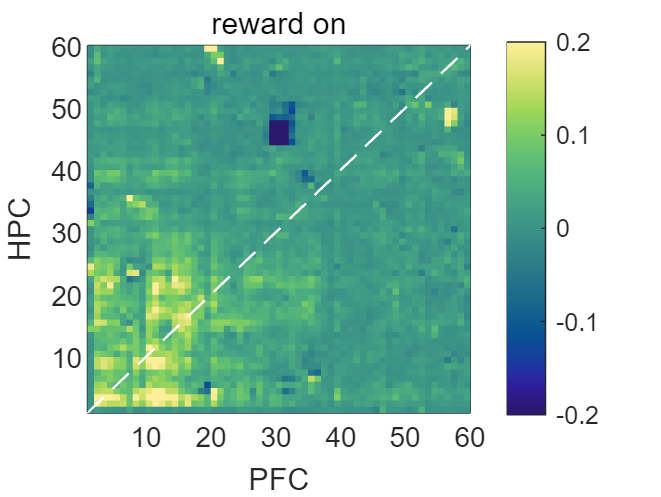

lindist_trajbound3 = meanMatrix3;
%lindist_trajbound3 = conv2(lindist_trajbound3, h, 'same');

% heatmap
figure;
t = pcolor(lindist_trajbound3);
%shading interp;

caxis([-0.2 0.2]);
cmocean('haline')
colorbar

%{
%caxis([-0.4 0.4]);
colormap(cmap);
colorbar;
%}

set(t, 'EdgeColor', 'none');
line([1 60], [1 60], 'Color', [1,1,1], 'LineWidth', 0.8,"LineStyle", "--");

xlabel('PFC');
ylabel('HPC');
title('reward on');

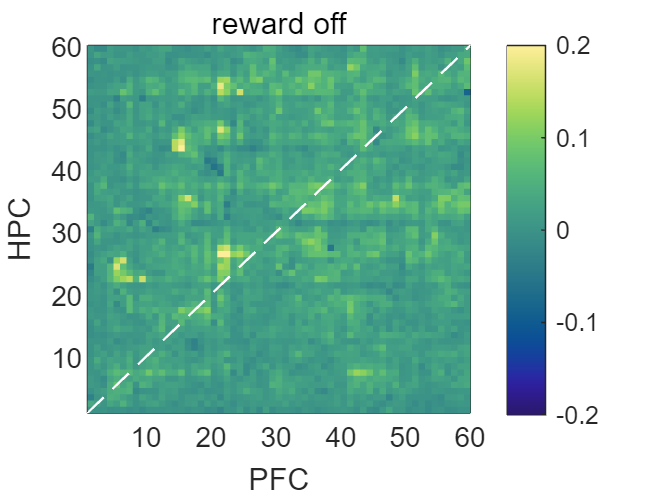

lindist_trajbound4 = meanMatrix4;
%lindist_trajbound = conv2(lindist_trajbound4, h, 'same');

% heatmap
figure;
t = pcolor(lindist_trajbound4);
%shading interp;

caxis([-0.2 0.2]);
cmocean('haline')
colorbar

%{
%caxis([-0.4 0.4]);
colormap(cmap);
colorbar;
%}

set(t, 'EdgeColor', 'none');
line([1 60], [1 60], 'Color', [1,1,1], 'LineWidth', 0.8,"LineStyle", "--");

xlabel('PFC');
ylabel('HPC');
title('reward off');

asymmetry_indices = zeros(50, 30);
A = stackedMatrices3;

for i = 1:50
    a = 14;
    for t = 1:30
        matrix1 = A{i};

        left_half = matrix1(t:(t+14-a),(t-14+a):t);
        left_avg = mean(diag(flipud(left_half)));
        right_half = matrix1((t-14+a):t,t:(t+14-a));
        right_avg = mean(diag(flipud(right_half)));
        disp(size(left_half))
        asymmetry_indices(i,t) = right_avg - left_avg;
        if t <= 14
            a = a-1;
        elseif t >= 16
            a = a+1;
        else
            a = 0;
        end 
    end   
end

     1     1

     2     2

     3     3

     4     4

     5     5

     6     6

     7     7

     8     8

     9     9

    10    10

    11    11

    12    12

    13    13

    14    14

    15    15

    15    15

    14    14

    13    13

    12    12

    11    11

    10    10

     9     9

     8     8

     7     7

     6     6

     5     5

     4     4

     3     3

     2     2

     1     1

     1     1

     2     2

     3     3

     4     4

     5     5

     6     6

     7     7

     8     8

     9     9

    10    10

    11    11

    12    12

    13    13

    14    14

    15    15

    15    15

    14    14

    13    13

    12    12

    11    11

    10    10

     9     9

     8     8

     7     7

     6     6

     5     5

     4     4

     3     3

     2     2

     1     1

     1     1

     2     2

     3     3

     4     4

     5     5

     6     6

     7     7

     8     8

     9     9

    10    10

    11    11

    12

A = asymmetry_indices;
p_values = zeros(1, 30);
conf_intervals = zeros(2, 30);
a_i = mean(A);

% 对每一列进行T检验
for i = 1:30
    [~, p_values(i)] = ttest(A(:, i)); % 进行T检验，返回p值
    
    % 计算95%置信区间
    mean_val = mean(A(:, i));
    std_val = std(A(:, i));
    margin_of_error = tinv(0.975, 29) * std_val / sqrt(30); % 使用T分布的临界值
    conf_intervals(:, i) = [mean_val - margin_of_error; mean_val + margin_of_error];
end

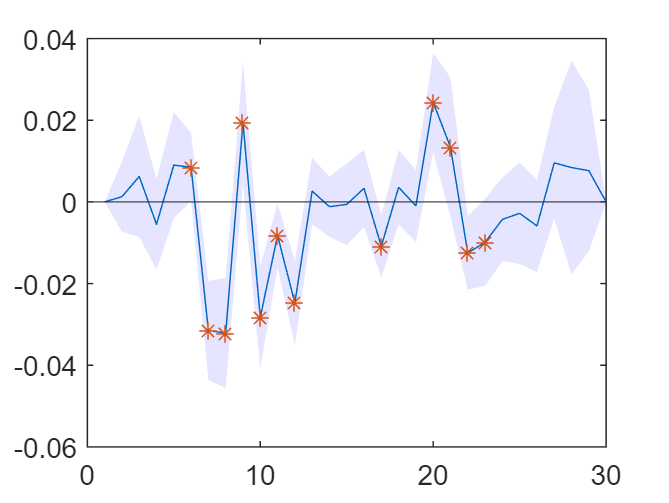

% 创建一个新的图形窗口
figure;

plot(a_i);
hold on
x = 1:length(a_i);
fill([x, fliplr(x)], [conf_intervals(1, :), fliplr(conf_intervals(2, :))], 'b','FaceAlpha', 0.1, 'EdgeColor', 'none');
hold on
significant_points = p_values <= 0.05;
scatter(x(significant_points), a_i(significant_points), 36, '*'); % 使用RGB颜色

yline(0);

Patterns(1,2,2)

ans = 包含以下字段的 struct :
           X_source: [79×11550 double]
           X_target: [53×11550 double]
        rankRegress: []
     factorAnalysis: []
              jpecc: []
             X_time: [2.0908e+03 2.0909e+03 2.0909e+03 2.0909e+03 2.0910e+03 2.0910e+03 2.0910e+03 2.0911e+03 2.0911e+03 2.0911e+03 2.0912e+03 2.0912e+03 2.0912e+03 2.0913e+03 2.0913e+03 2.0913e+03 2.0914e+03 2.0914e+03 2.0914e+03 2.0915e+03 … ]
       index_source: [1 6 7 8 12 13 15 18 19 22 23 24 27 28 32 33 34 36 38 39 40 43 44 47 48 50 51 53 54 57 58 60 62 63 65 70 71 72 74 75 76 77 80 82 84 86 87 88 89 91 92 93 94 95 97 98 99 101 103 104 105 106 107 109 112 113 114 117 118 119 120 121 … ]
       index_target: [25 31 57 26 45 67 29 42 65 72 59 75 39 54 30 11 51 24 53 10 73 38 64 28 46 71 61 40 4 37 22 14 27 8 41 62 17 13 34 7 58 50 32 56 18 69 16 12 33 5 47 19 20]
    index_og_source: [7 12 13 14 18 19 21 24 25 28 29 30 33 34 38 39 40 42 44 45 46 49 50 53 54 56 57 59 60 63 64 66 68 69 71 76 77 78 80 81 82 83 86 

heatmap for correlation

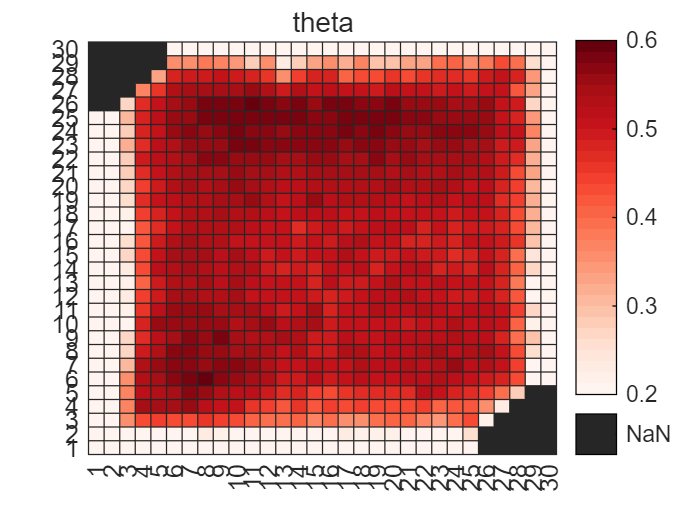

%{
heatmap(nd.fieldGet(Patterns(3).jpecc, "val1"), "Colormap", turbo, "ColorLimits", [-0.3,0.7], "Title", Patterns(1).name)
heatmap(nd.fieldGet(Patterns(7).jpecc, "val1"), "Colormap", turbo, "ColorLimits", [-0.3,0.7], "Title", Patterns(5).name)
heatmap(nd.fieldGet(Patterns(11).jpecc, "val1"), "Colormap", turbo, "ColorLimits", [-0.3,0.7], "Title", Patterns(9).name)
heatmap(nd.fieldGet(Patterns(15).jpecc, "val1"), "Colormap", turbo, "ColorLimits", [-0.3,0.7], "Title", Patterns(13).name)
heatmap(nd.fieldGet(Patterns(19).jpecc, "val1"), "Colormap", turbo, "ColorLimits", [-0.3,0.7], "Title", Patterns(17).name)
heatmap(nd.fieldGet(Patterns(23).jpecc, "val1"), "Colormap", turbo, "ColorLimits", [-0.3,0.7], "Title", Patterns(21).name)
%}


theta_ave = (nd.fieldGet(Patterns(3).jpecc, "val1") + nd.fieldGet(Patterns(4).jpecc, "val1"))/2;
theta_ave = conv2(theta_ave, h, 'same');
h1 = heatmap(theta_ave, "Title", Patterns(3).name);
colormap(brewermap(32,'Reds'))
caxis([0.2 0.6])
colorbar
h1.YDisplayData = flipud(h1.YDisplayData);
h1.YDisplayLabels = flip(1:30);

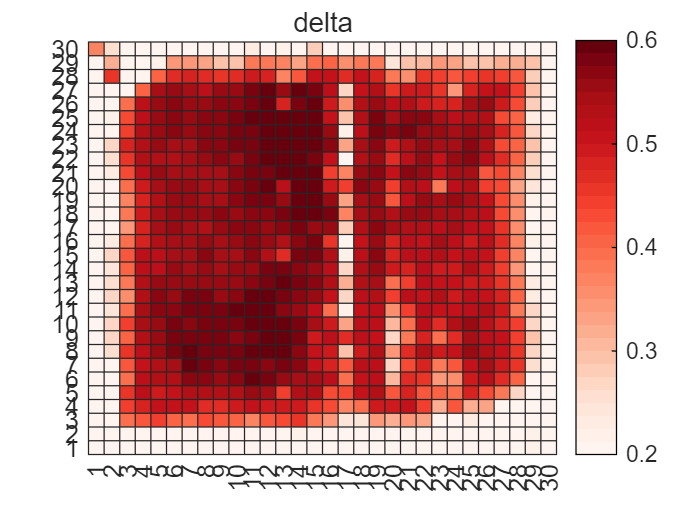


delta_ave = (nd.fieldGet(Patterns(7).jpecc, "val1") + nd.fieldGet(Patterns(8).jpecc, "val1"))/2;
delta_ave = conv2(delta_ave, h, 'same');
h2 = heatmap(delta_ave, "Title", Patterns(5).name);
colormap(brewermap(32,'Reds'))
caxis([0.2 0.6])
colorbar
h2.YDisplayData = flipud(h2.YDisplayData);
h2.YDisplayLabels = flip(1:30);

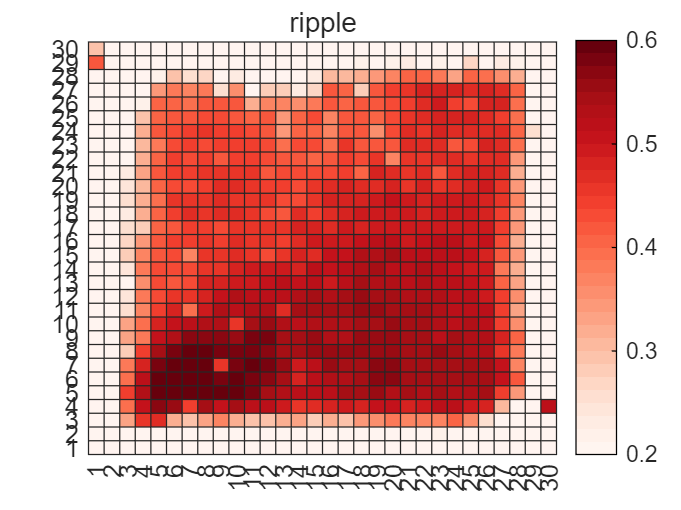


ripple_ave = (nd.fieldGet(Patterns(11).jpecc, "val1") + nd.fieldGet(Patterns(12).jpecc, "val1"))/2;
ripple_ave = conv2(ripple_ave, h, 'same');
h3 = heatmap(ripple_ave, "Title", Patterns(11).name);
colormap(brewermap(32,'Reds'))
caxis([0.2 0.6])
colorbar
h3.YDisplayData = flipud(h3.YDisplayData);
h3.YDisplayLabels = flip(1:30);

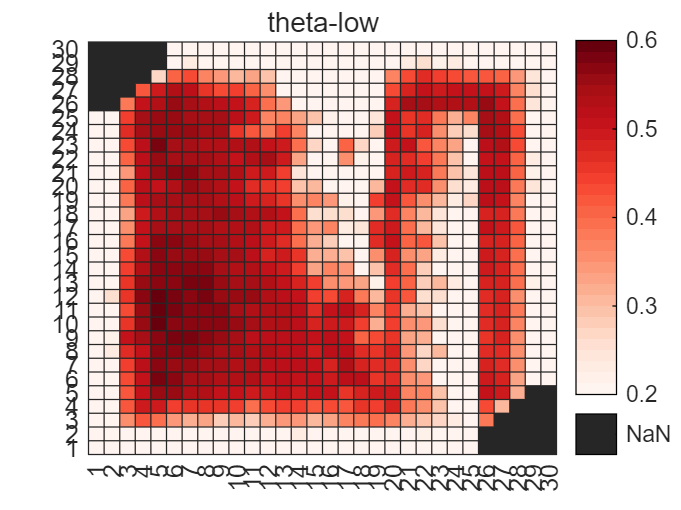


theta_control_ave = (nd.fieldGet(Patterns(15).jpecc, "val1") + nd.fieldGet(Patterns(16).jpecc, "val1"))/2;
theta_control_ave = conv2(theta_control_ave, h, 'same');
h4 = heatmap(theta_control_ave, "Title", "theta-low");
colormap(brewermap(32,'Reds'))
caxis([0.2 0.6])
colorbar
h4.YDisplayData = flipud(h4.YDisplayData);
h4.YDisplayLabels = flip(1:30);

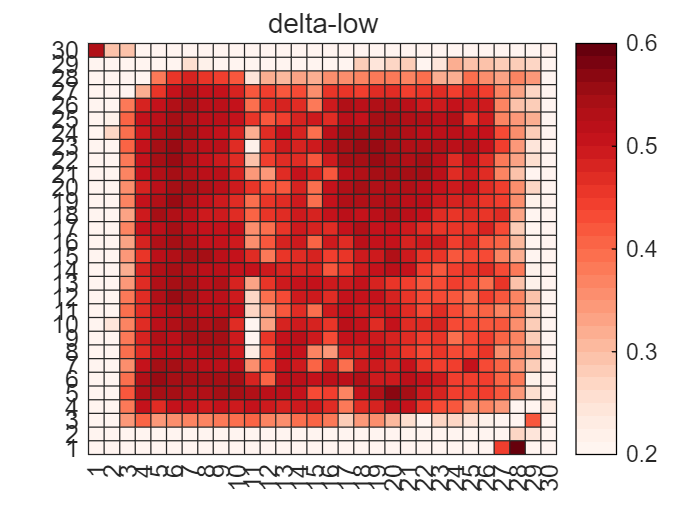


delta_control_ave = (nd.fieldGet(Patterns(19).jpecc, "val1") + nd.fieldGet(Patterns(20).jpecc, "val1"))/2;
delta_control_ave = conv2(delta_control_ave, h, 'same');
h5 = heatmap(delta_control_ave, "Title", "delta-low");
colormap(brewermap(32,'Reds'))
caxis([0.2 0.6])
colorbar
h5.YDisplayData = flipud(h5.YDisplayData);
h5.YDisplayLabels = flip(1:30);

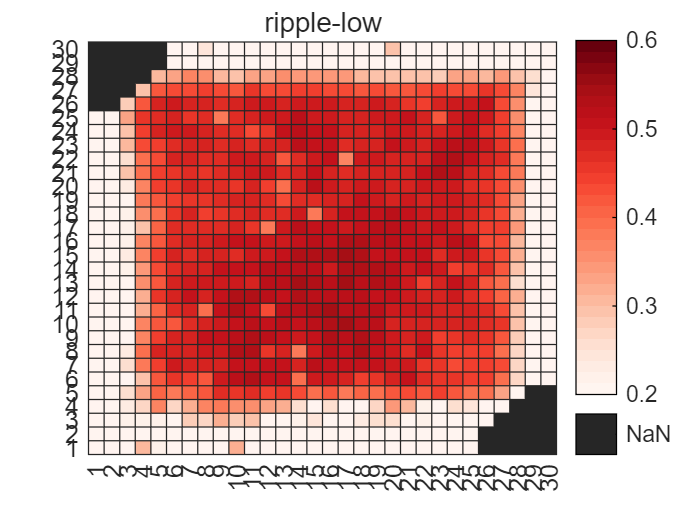


ripple_control_ave = (nd.fieldGet(Patterns(23).jpecc, "val1") + nd.fieldGet(Patterns(24).jpecc, "val1"))/2;
ripple_control_ave = conv2(ripple_control_ave, h, 'same');
h6 = heatmap(ripple_control_ave, "Title", "ripple-low");
colormap(brewermap(32,'Reds'))
caxis([0.2 0.6])
colorbar
h6.YDisplayData = flipud(h6.YDisplayData);
h6.YDisplayLabels = flip(1:30);

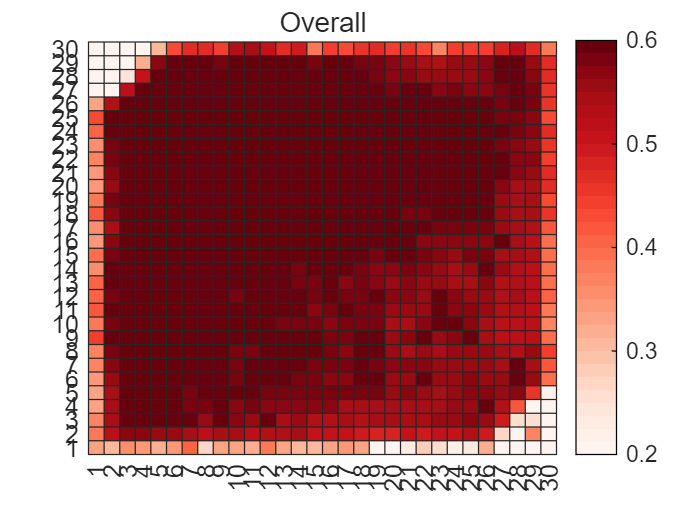


overall = nd.fieldGet(Patterns_overall(2,7).jpecc, "val1");
overall = conv2(overall, h, 'same');
h7 = heatmap(overall, "Title", Patterns_overall(2,7).name);
colormap(brewermap(32,'Reds'))
caxis([0.2 0.6])
colorbar
h7.YDisplayData = flipud(h7.YDisplayData);
h7.YDisplayLabels = flip(1:30);

`asymmetry_index`

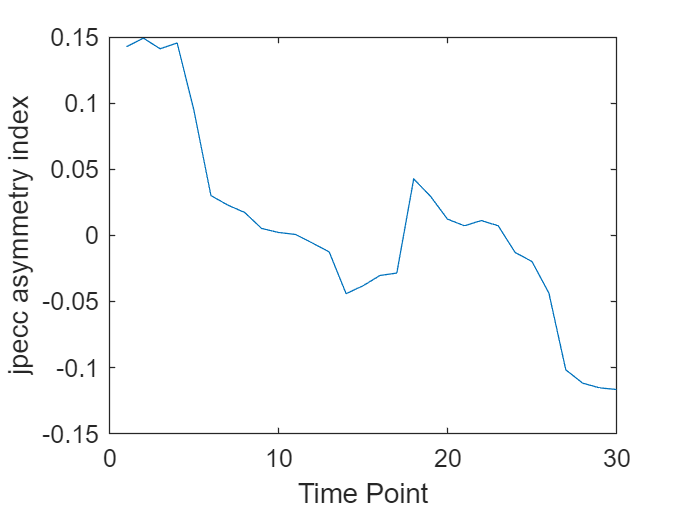

all_ai = zeros(2, 30);

for i = 7:8
    jpecc_val = nd.fieldGet(Patterns(i).jpecc, "val1");

    % Initialize the asymmetry index
    asymmetry_index = zeros(size(jpecc_val, 1), 1);

% Loop over each time point
for t = 1:30
    % Calculate the indices for the left and right slices
    left_slice_indice = max(1, t-3);
    right_slice_indice = min(30, t+3);
    
    % Extract the slices from the jPECC matrix
    diag_slice = jpecc_val(left_slice_indice:right_slice_indice, left_slice_indice:right_slice_indice);
    
    % Calculate the averages for each slice
    mid_point = floor(size(diag_slice, 1) / 2);
    left_avg = mean(mean(diag_slice(1:mid_point, 1:mid_point)));
    right_avg = mean(mean(diag_slice(mid_point+1:end, mid_point+1:end)));
    
    % Calculate the asymmetry index for this time point
    asymmetry_index(t) = right_avg - left_avg;
end

    all_ai(i-2,:) = asymmetry_index;

end
    figure;
    plot(mean(all_ai, 1));
    xlabel('Time Point');
    ylabel('jpecc asymmetry index');



% Use t-test to compare asymmetry_index with 0
p_values = zeros(1, 30);

for i = 1:30
    [~, p_values(i)] = ttest(all_ai(:, i), 0);
end

disp(p_values);

  列 1 至 10

    0.1885    0.1848    0.1766    0.1763    0.1798    0.2226    0.1867    0.1787    0.4744    0.7946

  列 11 至 20

    0.9547    0.7586    0.3824    0.2654    0.3222    0.4453    0.3240    0.2726    0.2771    0.6416

  列 21 至 30

    0.3183    0.1749    0.4117    0.2908    0.1766    0.1937    0.1764    0.1765    0.1751    0.1758



草稿

norm_dist = reshape(Patterns(1,2,3).X_time,[30,2000])

norm_dist = 1.0e+04 *

    0.2010    0.2013    0.2015    0.2015    0.2015    0.2016    0.2016    0.2017    0.2018    0.2018    0.2018    0.2019    0.2032    0.2032    0.2035    0.2049    0.2050    0.2050    0.2051    0.2051    0.2051    0.2057    0.2057    0.2058    0.2058    0.2058    0.2058    0.2083    0.2083    0.2083    0.2083    0.2083    0.2083    0.2084    0.2084    0.2088    0.2089    0.2098    0.2098    0.2105    0.2114    0.2115    0.2115    0.2127    0.2127    0.2128    0.2128    0.2128    0.2128    0.2128
    0.2010    0.2013    0.2015    0.2015    0.2015    0.2016    0.2016    0.2017    0.2018    0.2018    0.2018    0.2019    0.2032    0.2032    0.2035    0.2050    0.2050    0.2050    0.2051    0.2051    0.2051    0.2057    0.2057    0.2058    0.2058    0.2058    0.2058    0.2083    0.2083    0.2083    0.2083    0.2084    0.2084    0.2084    0.2084    0.2088    0.2089    0.2098    0.2098    0.2105    0.2114    0.2115    0.2115    0.2127    0.2127    0.2128    0.2128    0.

norm_dist = norm_dist(3,:)

norm_dist = 1.0e+04 *

    0.2010    0.2013    0.2015    0.2015    0.2015    0.2016    0.2016    0.2017    0.2018    0.2018    0.2018    0.2019    0.2032    0.2032    0.2035    0.2050    0.2050    0.2050    0.2051    0.2051    0.2051    0.2057    0.2057    0.2058    0.2058    0.2058    0.2059    0.2083    0.2083    0.2083    0.2083    0.2084    0.2084    0.2084    0.2084    0.2088    0.2089    0.2098    0.2098    0.2105    0.2114    0.2115    0.2115    0.2127    0.2127    0.2128    0.2128    0.2128    0.2128    0.2129


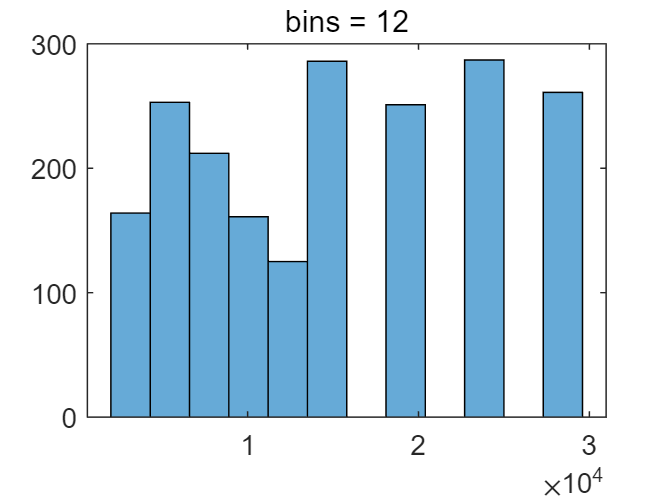


q1 = quantile(norm_dist, 0.25); % Compute the first quartile
q3 = quantile(norm_dist, 0.75); % Compute the third quartile
iqr = q3 - q1; % Compute the interquartile range

bin_width = 2 * iqr / (length(norm_dist) ^ (1 / 3)); % Compute the bin width using the Freedman-Diaconis rule
bin_count = ceil((max(norm_dist) - min(norm_dist)) / bin_width); % Compute the number of bins

figure; % Create a new figure
histogram(norm_dist, bin_count); % Create a histogram with the computed number of bins
title(['bins = ', num2str(bin_count)]); % Set the title of the figure

## CREATE TABLE AND SAVE RESULTS 

if Option.save
    
    disp("Saving results")
    
    % Ready the path
    table_folder = fullfile(codedefine(), 'DATA_TABLES');
    if ~exist(table_folder, 'dir')
        mkdir(table_folder);
    end
    if ~ismember(table_folder, path)
        addpath(table_folder);
    end

RunsSummary: Abbreviated summary of results for runs

    tableFolder = fullfile(string(codedefine()), "DATA_TABLES");
    tabname     = @(x) fullfile(tableFolder, x);
    if exist(tabname("RunsSummary" + Option.tableAppend + ".mat"), 'file')
        load(tabname("RunsSummary" + Option.tableAppend + ".mat"));
    else
        RunsSummary = [];
    end

DetailedRunsSummary: Summary of information for runs

    if exist(tabname("DetailedRunsSummary" + Option.tableAppend + ".mat"), 'file')
        load(tabname("DetailedRunsSummary" + Option.tableAppend + ".mat"));
    else
        warning("no existing DetailedRunsSummary table")
        DetailedRunsSummary = [];
    end
    
    % Identifying information about this options set and date of run
    hash      = DataHash(Option);
    hash      = hash(1:7); % Take the first 7 letters of the hash
    hash      = string(hash);
    timestamp = string(date());
    
    % Determine information to add to table
    Optim=params.getOptimizationParams(Patterns,Events,Option);
    Optimtable=struct2table(Optim);
    Optimtable.timestamp = timestamp;
    Optimtable.hash = hash;
    Optimtable.numWindowsCut = Events.nWindows
    Optimtable.cutoffs       = Events.cutoffs;
    
    % Create a table of options and table of patterns
    Optiontable  = struct2table(Option, 'AsArray', true);
    Patterntable = query.getPatternTable(Patterns);
    
    % Combine option columns with hash and date
    tablerow = [Optiontable, Optimtable];
    % Combine those with all rows of the pattern table
    tablecontent = util.table.flexibleColumnCat(Patterntable, ...
        repmat(tablerow, height(Patterntable), 1));

Check and Hash

    if ~isempty(RunsSummary)  &&any(contains(RunsSummary.hash, hash))
        RunsSummary(contains(RunsSummary.hash, hash), :) = []; % Delete any rows that contain the current hash
        DetailedRunsSummary(contains(DetailedRunsSummary.hash, hash), :) = [];
        disp("already computed before, rehashing to the same location");
        % New options:    Append row
    else
        disp("new results  --not in existing table")
    end
    
    % --------------------------------------
    % Append the new results and posrpocess
    % --------------------------------------
    if istable(DetailedRunsSummary)
        old_height = height(DetailedRunsSummary);
    else
        old_height = 0;
    end
    fields_equal = isequal(fields(DetailedRunsSummary), fields(tablecontent))
    if  old_height ~= 0 ||~fields_equal
        ~isequal(fields(DetailedRunsSummary), fields(tablecontent))
        DetailedRunsSummary = table.addNewColumn(DetailedRunsSummary, tablecontent);
        RunsSummary         = table.addNewColumn(RunsSummary, tablerow);
    else
        DetailedRunsSummary = [DetailedRunsSummary; tablecontent];
        RunsSummary         = [RunsSummary; tablerow];
    end
    assert(height(DetailedRunsSummary) > old_height, "appending failed!");
    DetailedRunsSummary = table.postprocessSummaryTable(DetailedRunsSummary);
    RunsSummary         = table.postprocessSummaryTable(RunsSummary);

## ------------- Save ----------------------------

save the tables

    save(tabname("RunsSummary" + Option.tableAppend),         "RunsSummary",         '-v7.3');
    save(tabname("DetailedRunsSummary" + Option.tableAppend), "DetailedRunsSummary", '-v7.3');
    % save the results
    saveVars = {'Option'};
    if exist('Patterns','var')
        saveVars = [saveVars, {'Patterns', 'Patterns_overall'}];
    end
    if exist('Components', 'var')
        saveVars = [saveVars, {'Components', 'Components_overall'}];
    end
    thisFile = fullfile(codedefine, "hash", hash + ".mat");
    disp("Saving ...");
    tic; save(thisFile, saveVars{:},'-v7.3');
    disp("... " + toc + " seconds");
    % link most recent state
    pushd(hashdefine());
    recencyName = Option.animal + "_" + replace(Option.generateH," ", "") + ...
        "_mostRecentState.mat";
    system("ln -sf " + hash + ".mat " + recencyName);
    popd()
    % save raw?
    if Option.saveRaw
        disp("Saving raw...");
        tic; save(thisFile, "Events", "Spk",'-v7.3', '-append');
        disp("... " + toc + " seconds");
    end
    
end
